# Denoising Using Low-Rank Approximation

## Introduction

The idea is  to identify the best way to approximate a given matrix $A$ with another one with a lower rank. Such a matrix is called a *low-rank approximation. *Usually, these methods imply imposing the target rank $k$, but in this tutorial we will focus on a relaxation using the nuclear norm.

**Low-Rank Structure in Data**

Many real-world datasets, especially those related to images, videos, and sensor readings, exhibit an underlying low-rank structure. This means that the essential information contained in the data can be represented by a matrix with significantly fewer non-zero singular values. For example, in images, pixels are often highly correlated due to the continuous nature of visual scenes, resulting in a low-rank representation. This redundancy can be exploited to distinguish between the meaningful signal and the random noise.

#### **Applications**

- **Compression - ** A low-rank approximation offers a compressed (albeit lossy) version of the matrix. While the original matrix A of size n x m is represented by nm numbers, describing it as a rank k matrix allows it to be eexpressed as $XY^T$ where $X$ is of size $n \times k$ and $Y$ of size $m \times k$, which  only requires  $k(n+m)$ numbers. If $k$ is small compared to $n$ and $m$, substituting their product with their sum yields significant savings.

- **Robust PCA - **Another example of matrix optimization problem involving a nuclear norm regularization is robust PCA. More generally, matrix optimization problems involving sparsity promoting criteria find broad applications in Data Science since they are at the core of techniques such as GLASSO or matrix completion.

- **Denoising -** If $A$ is a noisy version of some "ground truth" signal that is approximately low-rank, then approximating $A$ with a low-rank matrix can effectively reduce noise while preserving the signal. This process results in a matrix that is more informative than the original noisy data.

- **Updating Big ML Models -  ** One modern application of low-rank matrix approximations is for fine-tuning large models. In the context of large language models (LLMs) with billions (or more) parameters, one often uses an off-the-shelf model trained on a vast, generic corpus (e.g., text from the web). Fine-tuning involves a second round of training on a domain-specific dataset, which is typically much smaller. Examples of fine-tuning tasks include datasets of customer service exchanges, Ed forum questions and answers, medical reports, etc. The challenge with fine-tuning is the computational expense of updating such large models. The 2021 paper "LORA: Low-Rank Adaptation of Large Language Models"  argues that fine-tuning updates are generally close to low-rank, and  one can explicitly learn these updates in their factorized form, effectively reducing the number of parameters to be trained.

Let's get started!

clear all
close all
clc

## 1. Load image and degrade data

We consider a denoising problem. We want to approximate the original image $x$ which was corrupted by additive noise.

$\tilde{x} = x + n$ , where $n\in \mathcal{N}(0, \alpha I)$.

You should create your own version of noisy image. 

Load the images provided in the folder and add a perturbation. You can control the perturbation level. Reseize the image to make it square.

N = 256;
Xtrue = imread('circ.png');
Xtrue = im2double(rgb2gray(Xtrue));
Xtrue = imresize(Xtrue, [N,N]);

sb = 0.3;
Xtilde = Xtrue+sb*randn(N,N);


Now plot the two images $x$ and $\tilde{x}$.

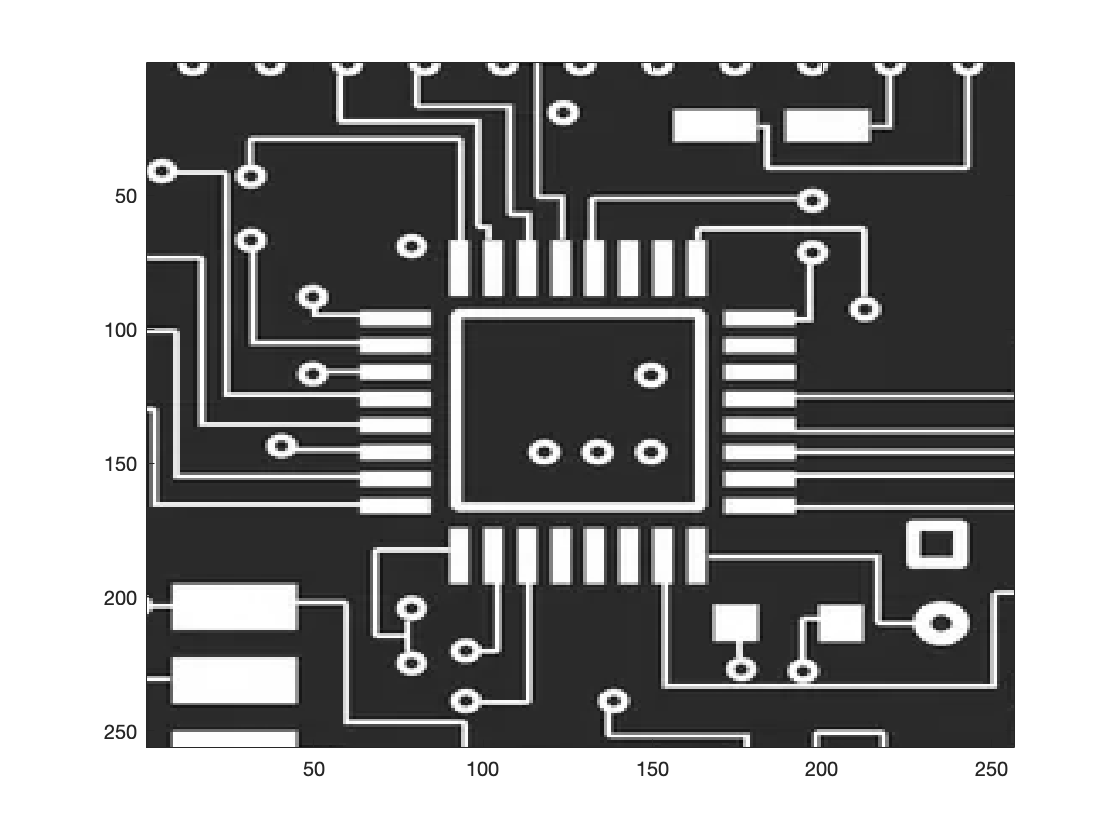

figure(1)
imagesc(Xtrue);
colormap(gray(256))

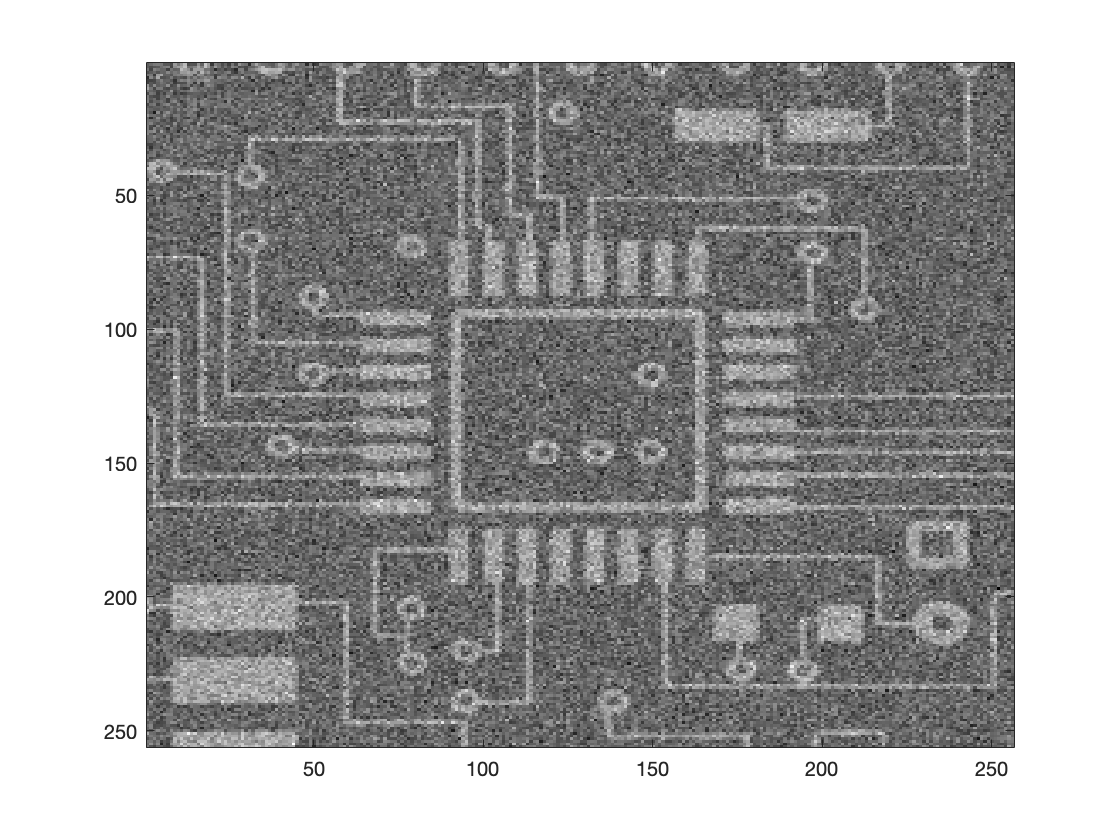

figure(2)
imagesc(Xtilde)
colormap(gray(256))

### 2. Dual Forward Backward

For this denosing problem we focus on nuclear norm penalization, considering the following optimization problem.

$x_\gamma = \text{argmin}_x \quad \frac{1}{2}\|\tilde{x} - x\|_{\rm{F}}^2 + \lambda\| x\|_*$,

where $\| \cdot \|_F$ is the Frobenius norm and $\| \cdot\|_*$ is the nuclear norm, i.e. the sum of the singular values of $x$. The nuclear norm regularization encourages the solution to have a low rank, making it effective in denoising.

To solve our problem, we will use Dual Forward-Backward algorithm, which is one of the most powerful proximal methods. More info about proximal algorithms can be found here: [http://proximity-operator.net](http://proximity-operator.net)

The algorithm to be implemented is as follows.

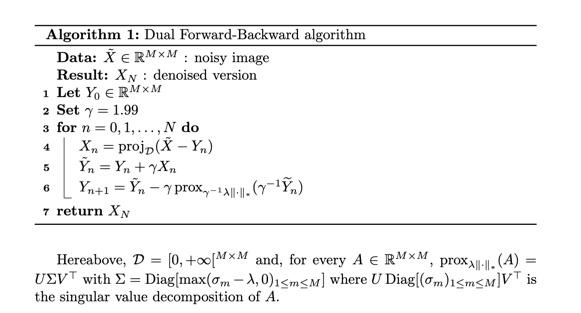

Implement the algorithm and play with different values of the hyperparameters to obtain the best results. Check the cost at each iteration and stop the algorithm if it reaches a certain precision.

edit DFB.m

### 3. Accelerated Dual-Forward Backward

There is also possible to implement an accelerated version of the algorithm. 

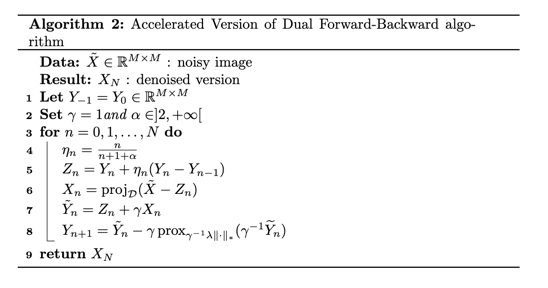

Write a Matlab function that implements the FISTA algorithm. Play with different values of the hyperparameters to obtain the best results. Check the cost at each iteration and stop the algorithm if it reaches a certain precision.

edit DFBa.m

### 4. Comparison

Compare the two methods from the convergence speed view-point. Plot the convergence curves of both algorithms on the same graph. 


nitm = 250;
lambda = 5;
prec = 1e-7;

[X,Y,cost,niter] = DFB(Xtilde,lambda,nitm,prec);

1: cost= 6181
2: cost= 5570.24
3: cost= 4724.65
4: cost= 5122.22
5: cost= 4562.35
6: cost= 4901.11
7: cost= 4458.55
8: cost= 4738.09
9: cost= 4382.69
10: cost= 4611.38
11: cost= 4325.07
12: cost= 4511.53
13: cost= 4280.5
14: cost= 4432.24
15: cost= 4245.65
16: cost= 4368.99
17: cost= 4218.21
18: cost= 4318.36
19: cost= 4196.46
20: cost= 4277.75
21: cost= 4179.17
22: cost= 4245.1
23: cost= 4165.36
24: cost= 4218.83
25: cost= 4154.31
26: cost= 4197.66
27: cost= 4145.45
28: cost= 4180.58
29: cost= 4138.33
30: cost= 4166.81
31: cost= 4132.6
32: cost= 4155.68
33: cost= 4127.98
34: cost= 4146.68
35: cost= 4124.25
36: cost= 4139.41
37: cost= 4121.25
38: cost= 4133.53
39: cost= 4118.82
40: cost= 4128.78
41: cost= 4116.86
42: cost= 4124.93
43: cost= 4115.28
44: cost= 4121.82
45: cost= 4114
46: cost= 4119.29
47: cost= 4112.96
48: cost= 4117.25
49: cost= 4112.13
50: cost= 4115.6
51: cost= 4111.45
52: cost= 4114.26
53: cost= 4110.9
54: cost= 4113.18
55: cost= 4110.46
56: cost= 4112.3
57: cost= 411

[X_F,Y_F,cost_F,niter_F] = DFBa(Xtilde,lambda,nitm,prec);

1: cost= 6181
2: cost= 6542.53
3: cost= 4573.34
4: cost= 4209.53
5: cost= 4139.26
6: cost= 4123.65
7: cost= 4119.01
8: cost= 4116.22
9: cost= 4114.09
10: cost= 4112.43
11: cost= 4111.32
12: cost= 4110.63
13: cost= 4110.24
14: cost= 4109.95
15: cost= 4109.72
16: cost= 4109.52
17: cost= 4109.35
18: cost= 4109.21
19: cost= 4109.12
20: cost= 4109.05
21: cost= 4108.98
22: cost= 4108.9
23: cost= 4108.83
24: cost= 4108.78
25: cost= 4108.74
26: cost= 4108.71
27: cost= 4108.69
28: cost= 4108.68
29: cost= 4108.66
30: cost= 4108.65
31: cost= 4108.64
32: cost= 4108.63
33: cost= 4108.62
34: cost= 4108.61
35: cost= 4108.61
36: cost= 4108.6
37: cost= 4108.6
38: cost= 4108.59
39: cost= 4108.59
40: cost= 4108.58
41: cost= 4108.58
42: cost= 4108.58
43: cost= 4108.58
44: cost= 4108.58
45: cost= 4108.58
46: cost= 4108.58
47: cost= 4108.57
48: cost= 4108.57
49: cost= 4108.57
50: cost= 4108.57
51: cost= 4108.57
52: cost= 4108.57
53: cost= 4108.57
54: cost= 4108.57
55: cost= 4108.57
56: cost= 4108.57


Compute the cost $\| x_N - x\|_{\rm{F}}$

norm(X-Xtrue,'fro')

ans = 36.9803

norm(X_F-Xtrue,'fro')

ans = 36.9803

Plot the results.

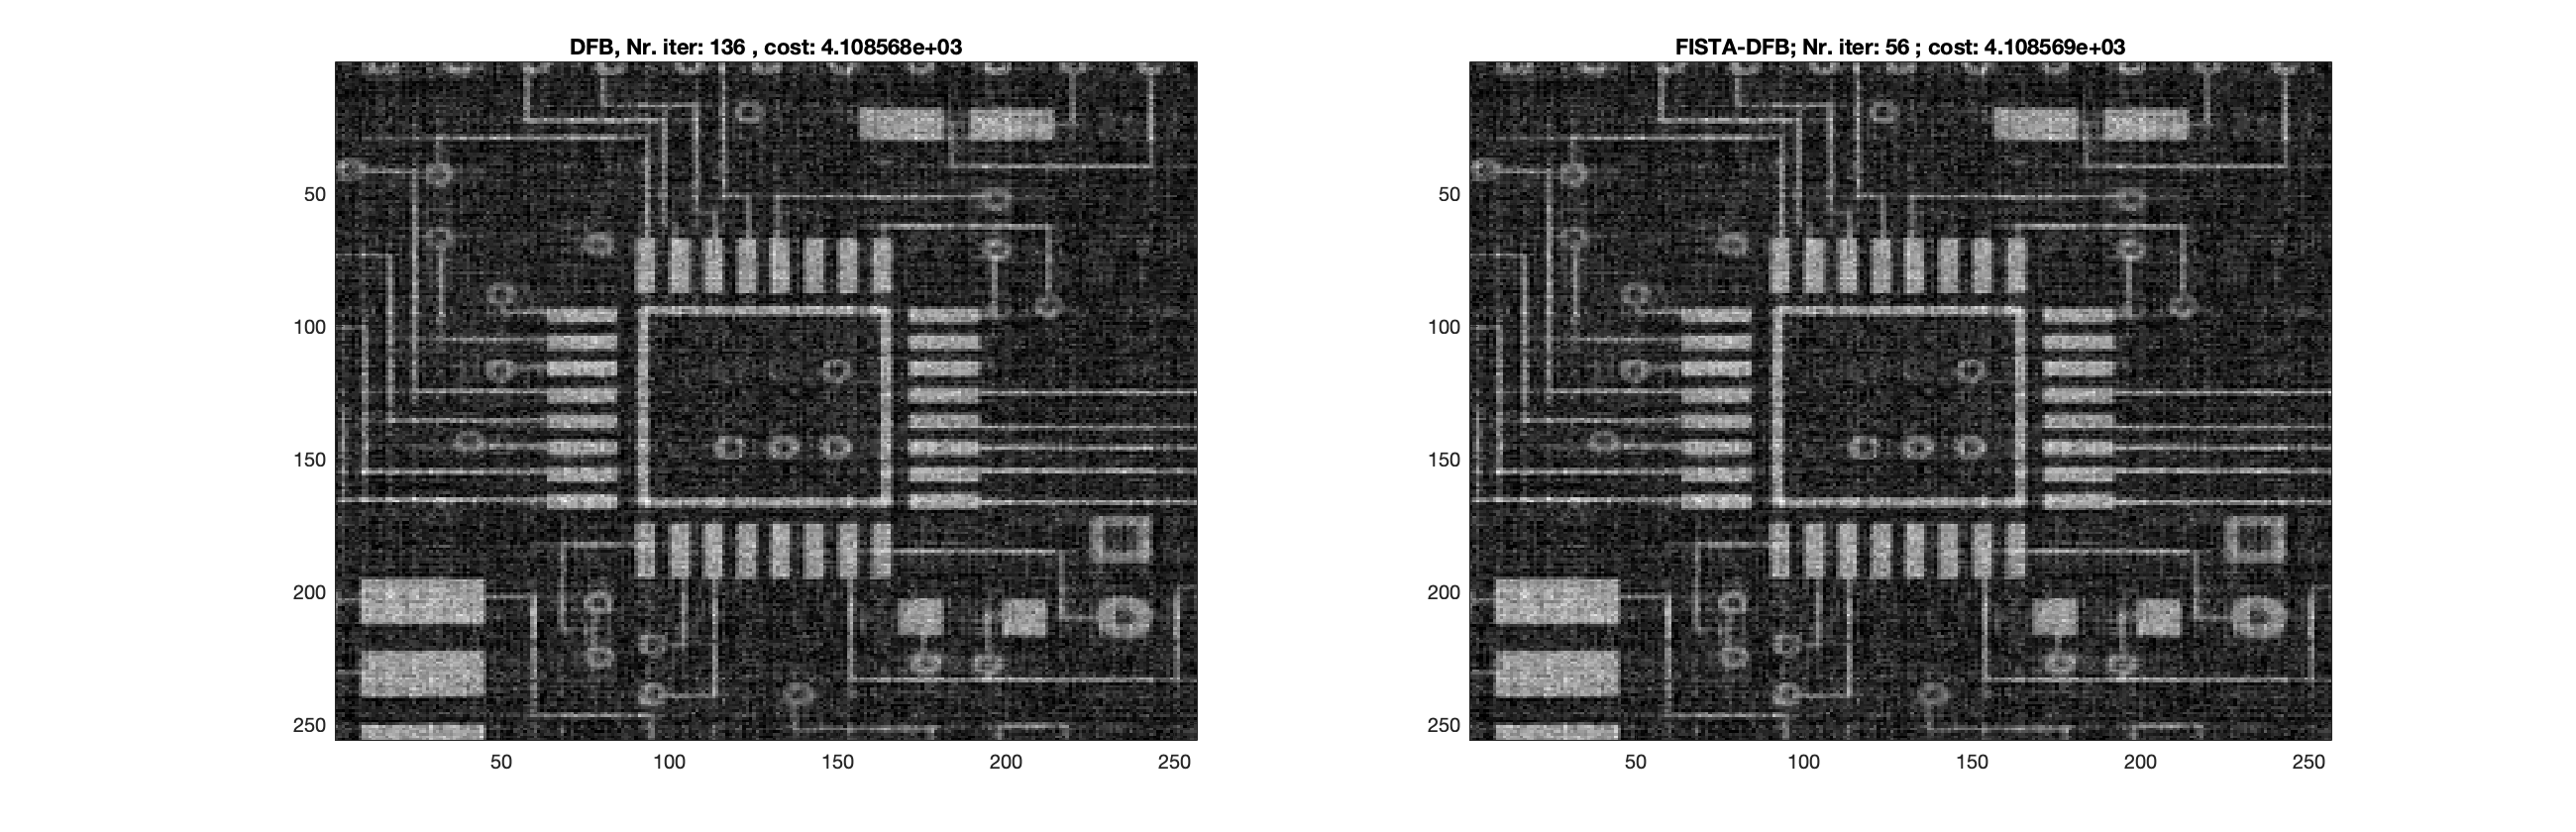

gcf = figure(3);
gcf.Position(3) = 1300;
hold on;
subplot(1,2,1)
imagesc(X)
colormap(gray(256))
title(sprintf("DFB, Nr. iter: %d , cost: %d",niter,cost(end)))

subplot(1,2,2)
imagesc(X_F)
colormap(gray(256))
title(sprintf("FISTA-DFB; Nr. iter: %d ; cost: %d",niter_F,cost_F(end)))

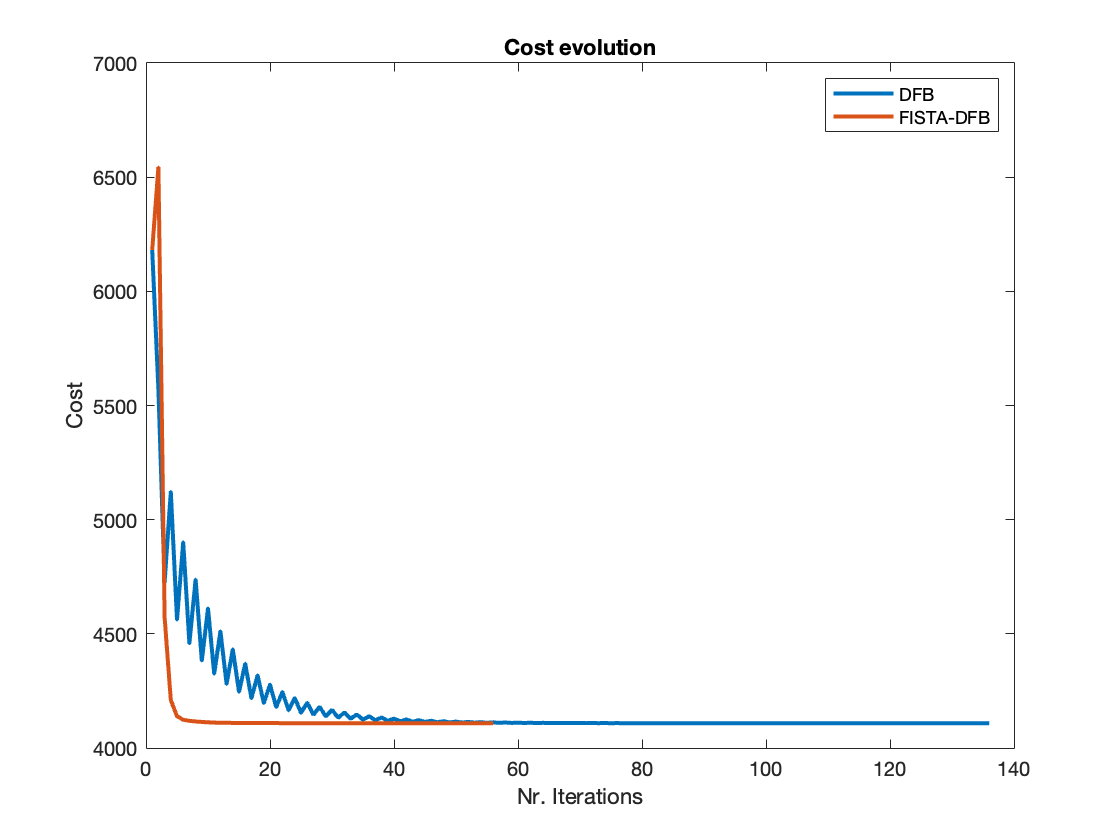

figure(4)
plot(cost,"LineWidth",2)
hold on;
plot(cost_F,"LineWidth",2)
legend("DFB","FISTA-DFB");
title("Cost evolution")
xlabel("Nr. Iterations")
ylabel("Cost")

### 5. Discussion

- What is the effect of the regularizer $\lambda$?

- Will this method work on all images? What are the best suited domains?

- What are the best values for the hyperparameters? Why?